clc
clear
close all

% 从csv中导入Q、I
fs=100;
% 滤波器测试数据
filename='G:\CODE\FYP_matlab\RawData\data (1).csv';
data_get=csvread(filename);
rawI = data_get(4700:5000,1);
rawQ = data_get(4700:5000,2);

%呼吸信号提取样本
% filename='G:\CODE\FYP_matlab\RawData\11_17_3.csv';
% data_get=csvread(filename);
% rawI = data_get(3000:10000,1);
% rawQ = data_get(3000:10000,2);

% t=linspace(0,length(rawI)/fs,length(rawI));
% length(rawI)
% plot(t,rawI)
% ylim([-3,3])
% title('rawI')
% xlabel('t/s');
% ylabel('Amp');
% plot(t,rawQ)
% ylim([-3,3])
% title('rawQ')
% xlabel('t/s');
% ylabel('Amp');

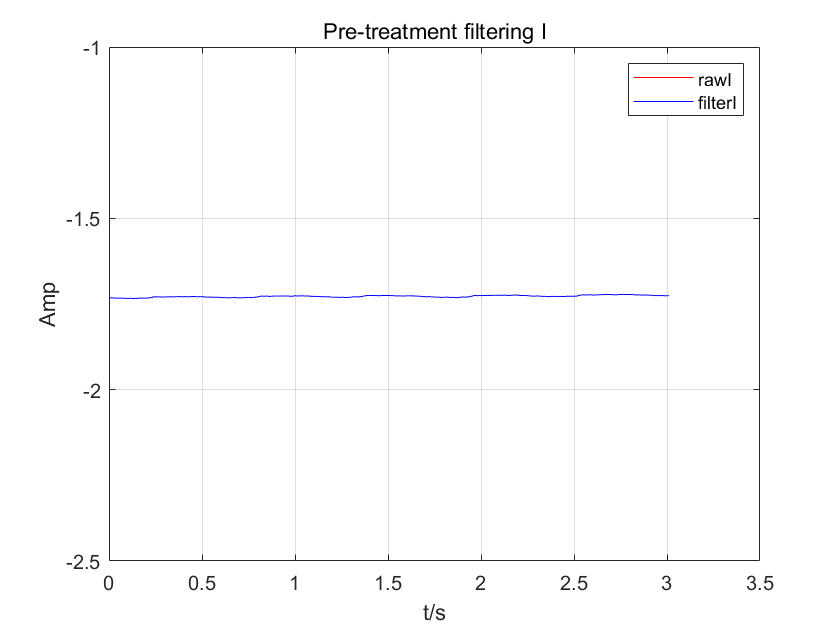

% View filter characteristics
hd = lowpass7;      % 根据自动生成滤波器的脚本文件名进行修改
[b,a]=tf(hd);            % 调用生成的滤波器
[H,W]=freqz(b,a);        % 数字滤波器系统函数
mag=abs(H);   % Amplitude
% db=20*log10((mag+eps)/max(mag));% convert to dB
db=20*log10(mag);% convert to dB
pha=angle(H); % Phase
 
% f2=W*fs/(2*pi)/(1e3); % convert to MHz units
f2=W*fs/(2*pi); % convert to MHz units
% notice：上述转换成频率公式中的1e4为生成滤波器时的采样频率
 
% subplot(3,2,3);plot(f2,db);
% title('Amplitude-frequency curve');
% xlabel('Frequency（Hz）');ylabel('Amplitude（dB）');
% subplot(3,2,4);plot(f2,pha);
% title('Phase-frequency curve');
% xlabel('Frequency（Hz）');ylabel('Phase（rad）');
 
% Start filter signal
% I_before_correction=filter(b,a,rawI); % a,b为系统函数的系数，x为待滤波的信号，y为滤波后输出后的信号
% Q_before_correction=filter(b,a,rawQ);
% I_before_correction=I_before_correction(1000:end);
% Q_before_correction=Q_before_correction(1000:end);


% % 忽略预处理滤波
I_before_correction=rawI; % a,b为系统函数的系数，x为待滤波的信号，y为滤波后输出后的信号
Q_before_correction=rawQ;
t=linspace(0,length(I_before_correction)/fs,length(I_before_correction));
% plot(t,rawI(1000:end),'r-',t,I_before_correction,'b-');
plot(t,rawI,'r-',t,I_before_correction,'b-');
grid on;
xlabel('t/s');
ylabel('Amp');
ylim([-2.5,-1])
legend('rawI','filterI');
title('Pre-treatment filtering I');

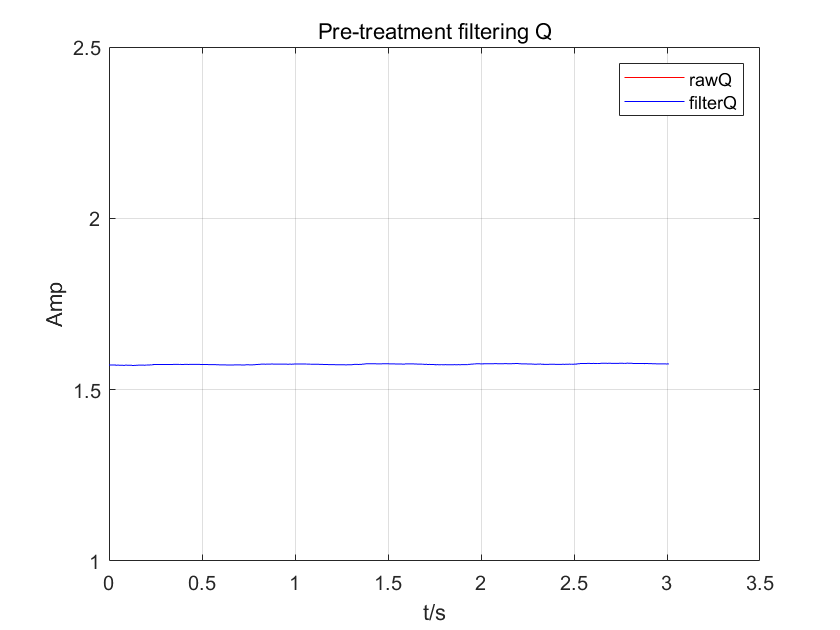

% title('预处理滤波（7Hz低通）后的I');

% plot(t,rawQ(1000:end),'r-',t,Q_before_correction,'b-');
plot(t,rawQ,'r-',t,Q_before_correction,'b-');
grid on;
xlabel('t/s');
ylabel('Amp');
ylim([1,2.5])
legend('rawQ','filterQ');
title('Pre-treatment filtering Q');

% title('预处理滤波（7Hz低通）后的I');

% ylim([-2.5,-1])
% plot(t,Q_before_correction)
% title('预处理滤波（7Hz低通）后的Q');
% ylim([-3,3])

% %IQ不平衡补偿
% %求均值
% I_before_correction = I_before_correction-mean(I_before_correction);
% Q_before_correction = Q_before_correction -mean(Q_before_correction);
% 
% %估计参数
% e = sqrt(mean(Q_before_correction.*Q_before_correction)/mean(I_before_correction.*I_before_correction))-1;
% phi = -asin(mean(I_before_correction.*Q_before_correction)/sqrt(mean(I_before_correction.*I_before_correction)*mean(Q_before_correction.*Q_before_correction)));
% %P矩阵求解
% P = [1,0;tan(phi),1/((1+e)*cos(phi))];
% 
% %计算IQ
% for i=1:length(I_before_correction)
% IQ(:,i) = P*[I_before_correction(i);Q_before_correction(i)];
% end
% %重组信号
% I =IQ(1,:);
% Q =IQ(2,:);

% signal_IQ = I+Q*1j;
% figure();
% pwelch(signal_IQ,  [],[],[],fs);title('Spectrum at Rx baseband after I/Q correction');

% 不考虑IQ不平衡
I =I_before_correction;
Q =Q_before_correction;

%图形绘制
% t=linspace(0,length(I)/fs,length(I));
% plot(t,I)
% ylim([-2,2])
% title('不平衡补偿后的I');
% plot(t,Q)
% ylim([-2,2])
% title('不平衡补偿后的Q');

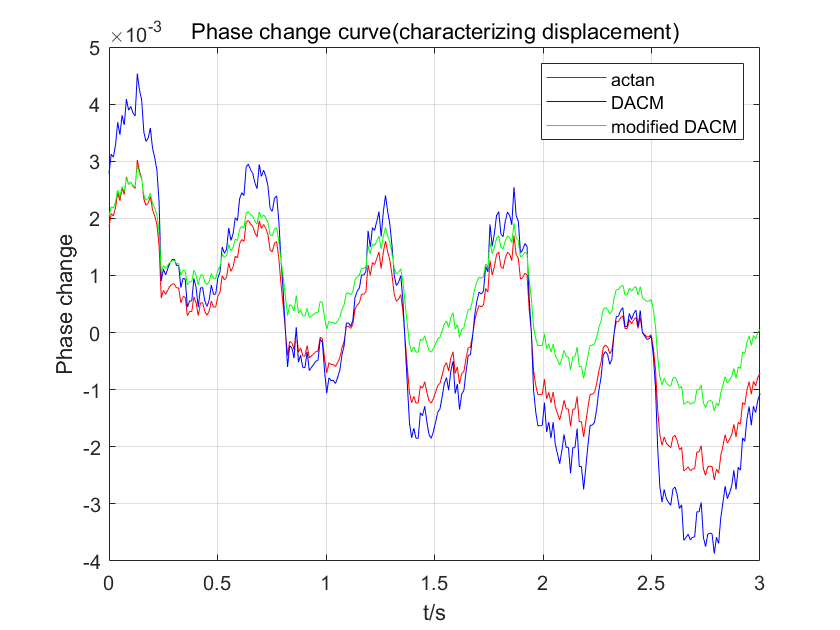

% IQ解调制

% 方法一actan
for i=1:length(I)
data_angle1(i) = atan(Q(i)/I(i));
end
data_angle1=unwrap(data_angle1);

% 方法二 DACM
data_angle2(1)=0;
addx=0;
for i=2:length(I)
    addx=addx+(I(i)*(Q(i)-Q(i-1))-Q(i)*(I(i)-I(i-1)))/(I(i)*I(i)+Q(i)*Q(i));
    data_angle2(i)=addx;
end

% 方法三 modified DACM
data_angle3(1)=0;
addx=0;
for i=2:length(I)
    addx=addx+(Q(i)*I(i-1)-Q(i-1)*I(i));
    data_angle3(i)=addx;
end
data_angle3=data_angle3/max(data_angle3);

t=linspace(0,length(data_angle1)/fs,length(data_angle1));
data_angle1=(data_angle1-mean(data_angle1));
data_angle2=(data_angle2-mean(data_angle2));
data_angle3=data_angle1-mean(data_angle3);

plot(t,data_angle1,'r-',t,data_angle2*1.5,'b-',t,data_angle3/1.3-1.218,'g-');
% plot(t,data_angle1);
grid on;
xlabel('t/s');
ylabel('Phase change');
% ylim([1,2.5])
xlim([0,3])
legend('actan','DACM','modified DACM');
title('Phase change curve(characterizing displacement)');

% plot(t,data_angle)
% title('相位变化(表征位移)');

% %对波形FFT
% N=length(data_angle1);
% n=0:N-1;
% % t=n/fs;
% 
% x1=fft(data_angle1,N);
% m1=abs(x1);
% x2=fft(data_angle2,N);
% m2=abs(x2);
% x3=fft(data_angle3,N);
% m3=abs(x3);
% 
% f=n*fs/N;
% % plot(f,m1,'r-',f,m2,'b-',f,m3,'g-');
% plot(f,m3);
% grid on;
% xlabel('frequency/Hz');
% ylabel('Amp');
% % legend('actan','DACM','modified DACM');
% title('FFT curve');
% % plot(f,m);
% xlim([0,3])
% 
% % ylim([0,100])


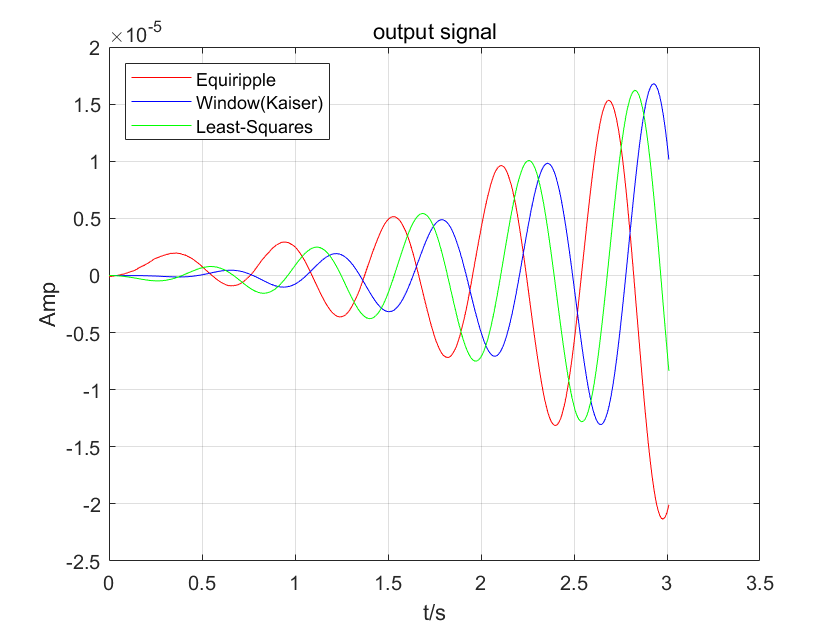

% View filter characteristics
% FIR equiripple

hd = bandpass1718;      % 根据自动生成滤波器的脚本文件名进行修改
[b,a]=tf(hd);            % 调用生成的滤波器
[H,W]=freqz(b,a);        % 数字滤波器系统函数
mag=abs(H);   % Amplitude
% db=20*log10((mag+eps)/max(mag));% convert to dB
db=20*log10(mag);% convert to dB
pha=angle(H); % Phase
 
f2=W*fs/(2*pi); % convert to MHz units
% notice：上述转换成频率公式中的1e4为生成滤波器时的采样频率
% figure(1)
% subplot(2,2,3);plot(f2,db);
% title('带通滤波器幅频曲线');
% xlabel('Frequency（Hz）');ylabel('Amplitude（dB）');
% % xlim([0,5])
% % ylim([-40,3])
% subplot(2,2,4);plot(f2,pha);
% title('带通滤波器相频曲线');
% xlabel('Frequency（Hz）');ylabel('Phase（rad）');
% xlim([0,5])
% Start filter signal 

% heart_signal=filter(b,a,data_angle);
% t=linspace(0,length(heart_signal)/fs,length(heart_signal));
% plot(t,heart_signal)
% title('心跳信号带通滤波');
% % xlim([40,45])
% grid on;




x=data_angle2;
t=linspace(0,length(data_angle2)/fs,length(data_angle2));
L=length(x);
x1=fftshift(fft(x));
ff=(-L/2:L/2-1)*fs/L;


bb=b;aa=a;
y_equi=filter(bb,aa,x); % 模拟输出 equiripple
y_equi1=fftshift(fft(y_equi));

hd = bandpass1718kaiser;      % 根据自动生成滤波器的脚本文件名进行修改
[b1,a1]=tf(hd);            % 调用生成的滤波器
bb=b1;aa=a1;
y_window=filter(bb,aa,x); % 模拟输出 window
y_window1=fftshift(fft(y_window));

hd = bandpass1718leastsquares2;      % 根据自动生成滤波器的脚本文件名进行修改
[b2,a2]=tf(hd);            % 调用生成的滤波器
bb=b2;aa=a2;
y_LeastSquares=filter(bb,aa,x); % 模拟输出 LeastSquares
y_LeastSquares1=fftshift(fft(y_LeastSquares));

plot(t,y_equi,'r-',t,y_window*35,'b-',t,y_LeastSquares*25,'g-');grid on;
legend('Equiripple','Window(Kaiser)','Least-Squares','Location','NorthWest');
xlabel ('t/s');
ylabel ('Amp');
title('output signal');

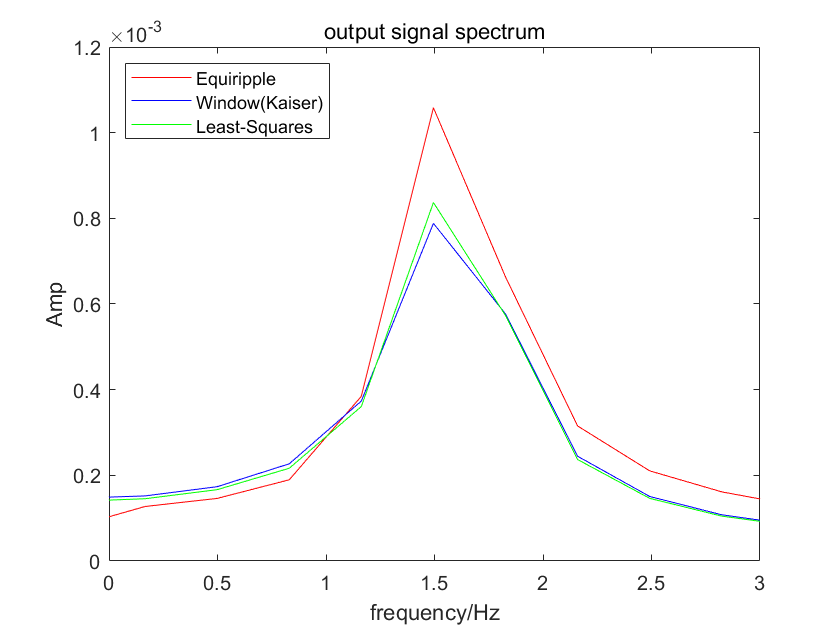


plot(ff,abs(y_equi1),'r-',ff,abs(y_window1)*35,'b-',ff,abs(y_LeastSquares1)*25,'g-');
legend('Equiripple','Window(Kaiser)','Least-Squares','Location','NorthWest');
xlabel('frequency/Hz');
ylabel('Amp');
title ('output signal spectrum');
xlim([0,3]);


% L=length(x);
% x1=fftshift(fft(x));
% ff=(-L/2:L/2-1)*fs/L;
% y1=fftshift(fft(y));
% figure(2)
% subplot(2,2,1)
% plot(t,x);
% xlabel ('t/s');
% ylabel ('Phase change');
% title('(a) input signal')
% subplot(2,2,2)
% plot(ff,abs(x1));
% xlabel('frequency/Hz');
% ylabel('Amp');
% title ('(b)input signal spectrum');
% xlim([0,3])
% % ylim([0,1])
% subplot(2,2,3)
% plot(t,y);grid on;
% xlabel ('t/s');
% ylabel ('Amp');
% title('(c)output signal');
% subplot(2,2,4)
% plot(ff,abs(y1));
% xlabel('frequency/Hz');
% ylabel('Amp');
% title ('(d)output signal spectrum');
% xlim([0,3]);

% % View filter characteristics
% hd = bandpass01503;      % 根据自动生成滤波器的脚本文件名进行修改
% [b,a]=tf(hd);            % 调用生成的滤波器
% [H,W]=freqz(b,a);        % 数字滤波器系统函数
% mag=abs(H);   % Amplitude
% % db=20*log10((mag+eps)/max(mag));% convert to dB
% db=20*log10(mag);% convert to dB
% pha=angle(H); % Phase
%  
% f2=W*fs/(2*pi); % convert to Hz units
% % notice：上述转换成频率公式中的1e4为生成滤波器时的采样频率
%  
% % subplot(3,2,3);plot(f2,db);
% % title('Amplitude-frequency curve');
% % xlabel('Frequency（Hz）');ylabel('Amplitude（dB）');
% % xlim([0,5])
% % ylim([-100,100])
% % subplot(3,2,4);plot(f2,pha);
% % title('Phase-frequency curve');
% % xlabel('Frequency（Hz）');ylabel('Phase（rad）');
% % xlim([0,5])
% 
% % Start filter signal
% respiration_signal=filter(b,a,data_angle3);
% t=linspace(0,length(respiration_signal)/fs,length(respiration_signal));
% plot(t,respiration_signal)
% xlabel('t/s');
% ylabel('Amp');
% xlim([30,50]);
% title('Respiratory signal');
% grid on;
% % plot(t(1:3000),respiration_signal(1:3000))


% % IIR数字滤波器(脉冲响应不变法)
% %  https://huchao.blog.csdn.net/article/details/117738598?spm=1001.2101.3001.6650.1&utm_medium=distribute.pc_relevant.none-task-blog-2%7Edefault%7EBlogCommendFromBaidu%7ERate-1-117738598-blog-21105857.pc_relevant_vip_default&depth_1-utm_source=distribute.pc_relevant.none-task-blog-2%7Edefault%7EBlogCommendFromBaidu%7ERate-1-117738598-blog-21105857.pc_relevant_vip_default&utm_relevant_index=2
% Wp=[1.7*2 1.8*2]/fs;
% Ws=[1.6*2 1.9*2]/fs;
% Ap=1;
% As=25;
% % Fs=100;
% T=1/fs;
% wp=(2/T)*tan(Wp/2);
% ws=(2/T)*tan(Ws/2);
% [N,wc]=cheb1ord(wp,ws,Ap,As,'s');
% wc=wp/(10^(0.1*Ap)-1)^(1/2/N);
% [num den]=butter(N,wc,'s');
% [numd,dend]=impinvar(num,den,fs);
% 
% w=linspace(0,pi,512);
% h=freqz(numd,dend,w);
% plot(w/pi,abs(h));
% title('脉冲响应不变法');
% % xlim([0,0.04])
% %计算所设计滤波器的Ap和As
% w1=[Wp,Ws];
% h1=freqz(numd,dend,w1);
% % fprintf('Ap= %.4f\n',-20*log10(abs(h1(1))));
% % fprintf('As= %.4f\n',-20*log10(abs(h1(2))));


% fpl = 2025; %通带较小频率
% fpu = 2225; %通带较大频率
% fsl = 1500; %阻带较小频率
% fsu = 2700; %阻带较大频率
%  
% ws = [2 * fpl / fs, 2 * fpu / fs];
% wp = [2 * fsl / fs, 2 * fsu / fs];
% Rp = 1;
% As = 40;
%  
% [N, wc] = buttord(wp, ws, Rp, As);%此时输入wp和ws都是二维的，输出wc也是两维的
% [B, A] = butter(N, wc);

% bb=b;aa=a;
% % bb=numd;aa=dend; %数字iir
% 
% x=data_angle;
% t=linspace(0,length(data_angle)/fs,length(data_angle));
% y=filter(bb,aa,x); % 模拟输出
% 
% L=length(x);
% x1=fftshift(fft(x));
% ff=(-L/2:L/2-1)*fs/L;
% y1=fftshift(fft(y));
% figure(2)
% subplot(2,2,1)
% plot(t,x);
% xlabel ('(a)输入信号');
% subplot(2,2,2)
% plot(ff,abs(x1));
% xlabel ('(b)输入信号频谱');
% xlim([0,3])
% subplot(2,2,3)
% plot(t,y);
% xlabel('(c)输出信号');
% subplot(2,2,4)
% plot(ff,abs(y1));
% xlabel ('(d)输出信号频谱');
% xlim([0,3])


% iir滤波器
% f_s1     =   1.6     ;   %阻带上截止频率
% f_s2    =  1.9;
% f_p1    =   1.7     ;   %通带下截止频率
% f_p2    =   1.8;
f_s1     =   1.3     ;   %阻带上截止频率
f_s2    =  1.7;
f_p1    =   1.4     ;   %通带下截止频率
f_p2    =   1.6;

R_p     =   0.5       ;   %通带允许的最大衰减
R_s    =   40     ;   %阻带允许的最小衰减
f_s     =   100    ;   %采样频率
T_s     =   1 / f_s ;   %采样间隔
%1.将数字高通滤波器的频率参数变换为归一化的数字角频率参数
omega_p1  = 2 * pi * f_p1  /f_s;
omega_s1 = 2 * pi * f_s1 /f_s;
omega_p2  = 2 * pi * f_p2  /f_s;
omega_s2 = 2 * pi * f_s2 /f_s;
%2.预畸变处理,将归一化数字角频率参数变换成模拟高通滤波器的角频率参数
C = 2 / T_s ;
Omega_p1   =C*tan( omega_p1  / 2 );
Omega_s1  = C*tan( omega_s1 / 2 ); 
Omega_p2   = C*tan( omega_p2  / 2 );
Omega_s2  = C*tan( omega_s2 / 2 );
W0=sqrt(Omega_p1*Omega_p2);
Omega_BW=Omega_p1-Omega_p2;
%3.对模拟高通滤波器的角频率参数做归一化处理
eta_sl      =   Omega_s1 / Omega_BW;
eta_p1       =   Omega_p1  / Omega_BW;   
eta_p2       =   Omega_p2  / Omega_BW;
eta_s2      =   Omega_s2 / Omega_BW;
%4.设计归一化模拟滤波器,得到归一化模拟高通滤波器的转移函数
wph=[Omega_p1,Omega_p2 ];
wsh=[Omega_s1,Omega_s2];
[ N1 , Wn1 ] = buttord( wph , wsh , R_p , R_s , 's' ); %选择模拟巴特沃斯滤波器的最小阶数

[N2,Wn2]=cheb1ord(wph,wsh,R_p,R_s,'s');       %求切比雪夫I型滤波器阶数
% [N,Wn]=cheb2ord(wph,wsh,R_p,R_s,'s');       %求切比雪夫II型滤波器阶数
[N3,Wn3]=ellipord(wph,wsh,R_p,R_s,'s');        %求椭圆型滤波器阶数

[ z1 , p1 , k1 ] = buttap(N1); %创建巴特沃斯模拟低通滤波器
[ z2 , p2 , k2 ] = buttap(N2); %创建切比雪夫模拟低通滤波器
[ z3 , p3 , k3 ] = buttap(N3); %创建椭圆型模拟低通滤波器
%[ Bp , Ap ] = zp2tf(z,p,k); %由零点、极点、增益确定传输函数的分子与分母系数
%5.利用归一化模拟高通滤波器的转移函数确定模拟高通滤波器的转移函数
BB1=real(poly(z1));
AA1=real(poly(p1));
[ b1 , a1 ] = lp2bp(BB1,AA1,W0,Omega_BW);
%6.利用模拟高通滤波器的转移函数确定IIR数字滤波器的转移函数 
[ bz1 , az1 ] = bilinear(b1,a1,f_s);

BB2=real(poly(z2));
AA2=real(poly(p2));
[ b2 , a2 ] = lp2bp(BB2,AA2,W0,Omega_BW);
%6.利用模拟高通滤波器的转移函数确定IIR数字滤波器的转移函数 
[ bz2, az2 ] = bilinear(b2,a2,f_s);

BB3=real(poly(z3));
AA3=real(poly(p3));
[ b3 , a3 ] = lp2bp(BB3,AA3,W0,Omega_BW);
%6.利用模拟高通滤波器的转移函数确定IIR数字滤波器的转移函数 
[ bz3 , az3 ] = bilinear(b3,a3,f_s);
% figure(1);
% freqz(bz,az);
% title('filter characteristic curve');


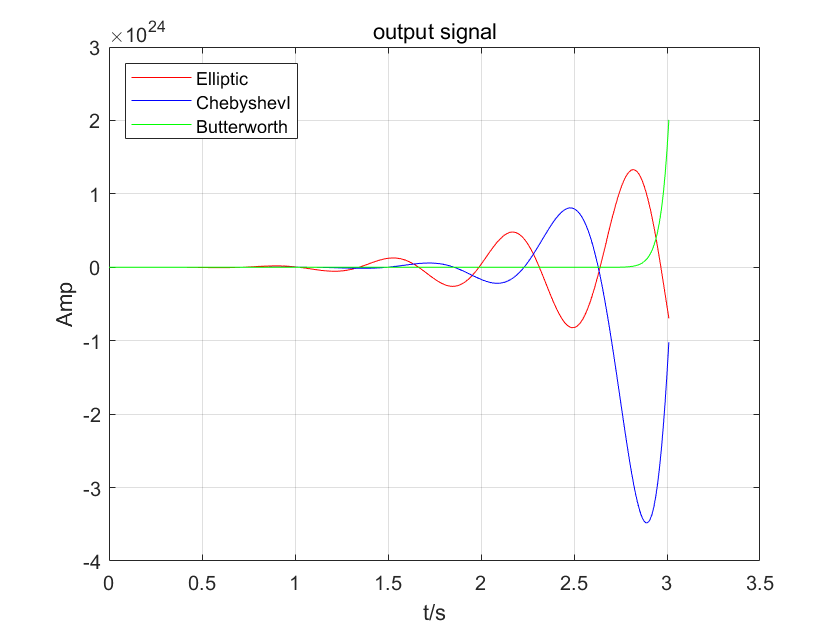

% bb=b;aa=a;


x=data_angle2;
t=linspace(0,length(data_angle2)/fs,length(data_angle2));
L=length(x);
x1=fftshift(fft(x));
ff=(-L/2:L/2-1)*fs/L;

bb=bz1;aa=az1; %数字iir
y_butterworth=filter(bb,aa,x); % 模拟输出
y_butterworth1=fftshift(fft(y_butterworth));

bb=bz2;aa=az2; %数字iir
y_cheb1ord=filter(bb,aa,x); % 模拟输出
y_cheb1ord1=fftshift(fft(y_cheb1ord));

bb=bz3;aa=az3; %数字iir
y_ellipord=filter(bb,aa,x); % 模拟输出
y_ellipord1=fftshift(fft(y_ellipord));

plot(t,y_ellipord*1000000000000000000000000000,'r-',t,y_cheb1ord*100000000000000000000000,'b-',t,y_butterworth,'g-');grid on;
legend('Elliptic','ChebyshevI','Butterworth','Location','NorthWest');
xlabel ('t/s');
ylabel ('Amp');
title('output signal');

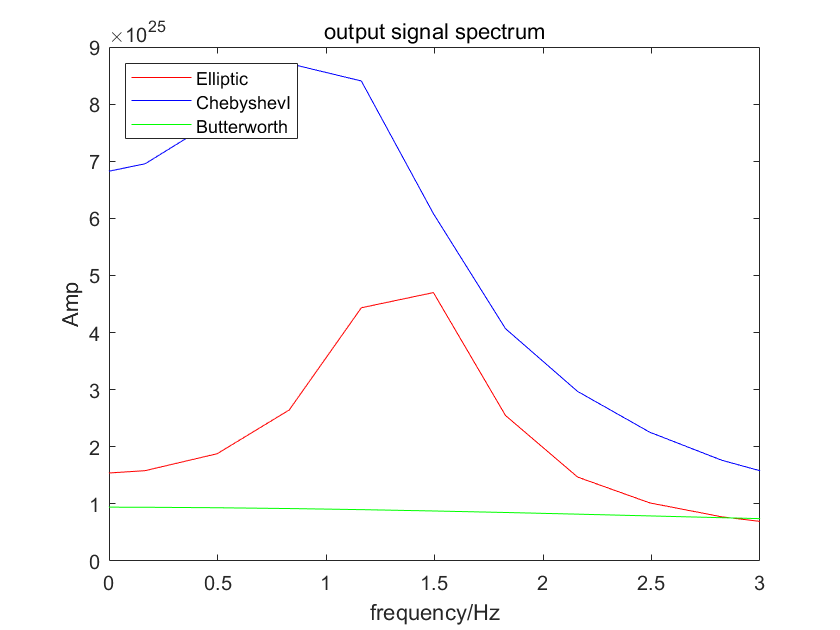


plot(ff,abs(y_ellipord1)*1000000000000000000000000000,'r-',ff,abs(y_cheb1ord1)*100000000000000000000000,'b-',ff,abs(y_butterworth1),'g-');
legend('Elliptic','ChebyshevI','Butterworth','Location','NorthWest');
xlabel('frequency/Hz');
ylabel('Amp');
title ('output signal spectrum');
xlim([0,3])

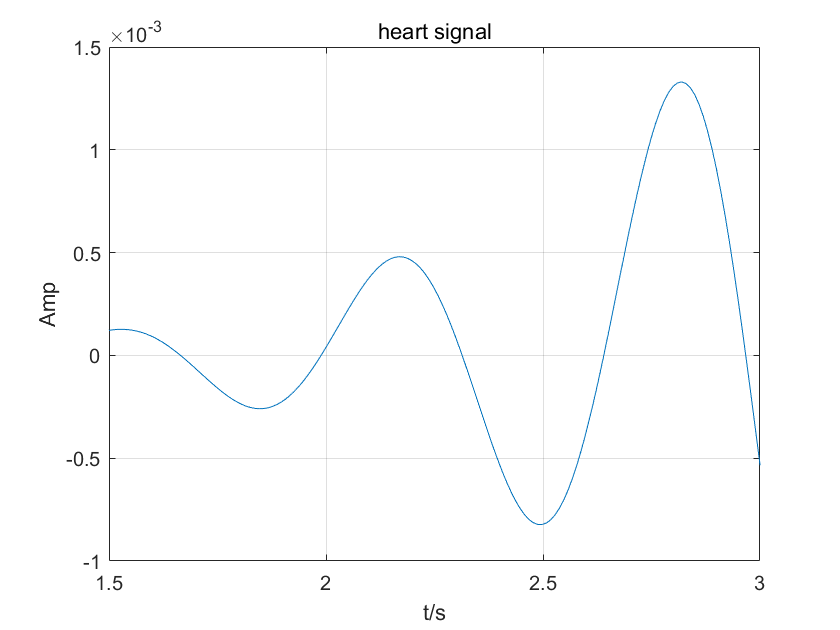


plot(t,y_ellipord);grid on;
title('heart signal');
xlabel ('t/s');
ylabel ('Amp');
xlim([1.5,3])

% figure(2)
% subplot(2,2,1)
% plot(t,x);
% xlabel ('(a)输入信号');
% subplot(2,2,2)
% plot(ff,abs(x1));
% xlabel ('(b)输入信号频谱');
% xlim([0,3])
% subplot(2,2,3)
% plot(t,y);grid on;
% xlabel('(c)输出信号');
% subplot(2,2,4)
% plot(ff,abs(y1));
% xlabel ('(d)输出信号频谱');
% xlim([0,3])